clear; close all;

h5disp('gammaray_lab4.h5');

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read('gammaray_lab4.h5','/data');
mydata(1,:)

ans =    940680016         315          45          10


## Problem 1: Meta Data

In the vast majority of scientific experiments there are many things that are being recorded. Metadata is the data behind the data. For example in the upcoming problem the 'main' data is the particle count, the thing we want to study, but we also have the GPS time, the satellites relative solar phase, the Earth's longitude, all alongside particle counts. All this data comes from a telescope in orbit that is used to study gamma-ray bursts. Just like in previous labs there is a background noise associated with the detector, coming from high energy particles. We can compare these data sets against each other and look for any trends or unusual data. The data has four columns and more than 25 million rows of data. The columns are 1) Time 2) Solar Phase 3) Earth Longitude 4) Particle Counts. 

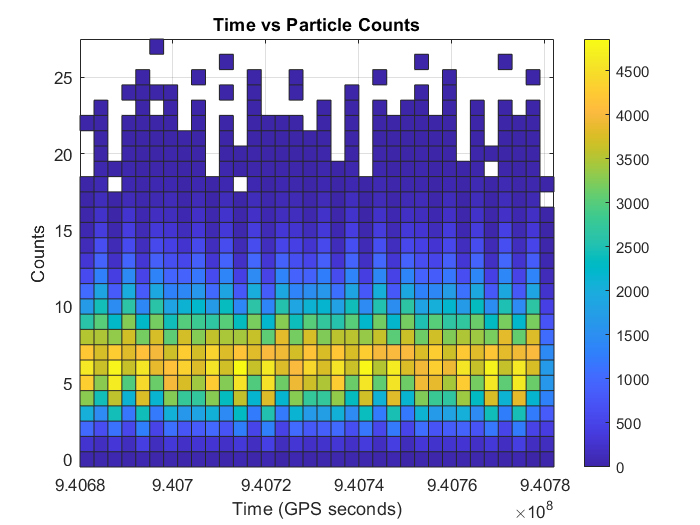

%columns are 1) Time 2) Solar Phase 3) Earth Longitude 4) Particle Counts

histogram2(mydata(1:1000000,1),mydata(1:1000000,4),'DisplayStyle','tile')
colorbar
title('Time vs Particle Counts')
xlabel('Time (GPS seconds)')
ylabel('Counts')

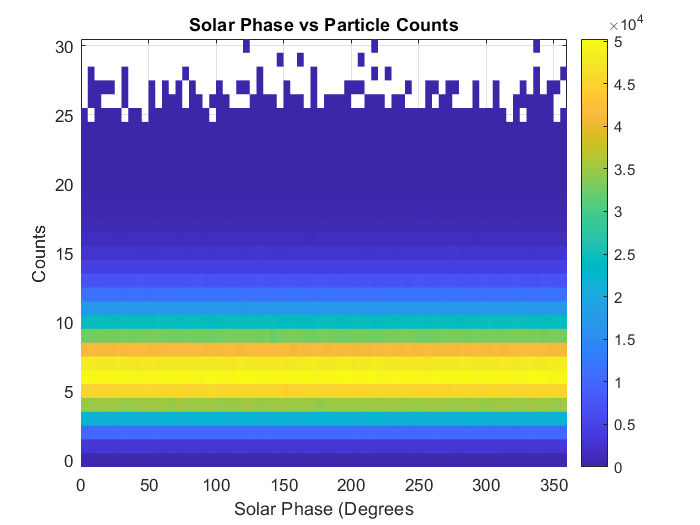

histogram2(mydata(1:end,2),mydata(1:end,4),'DisplayStyle','tile')
colorbar
title('Solar Phase vs Particle Counts')
xlabel('Solar Phase (Degrees')
ylabel('Counts')

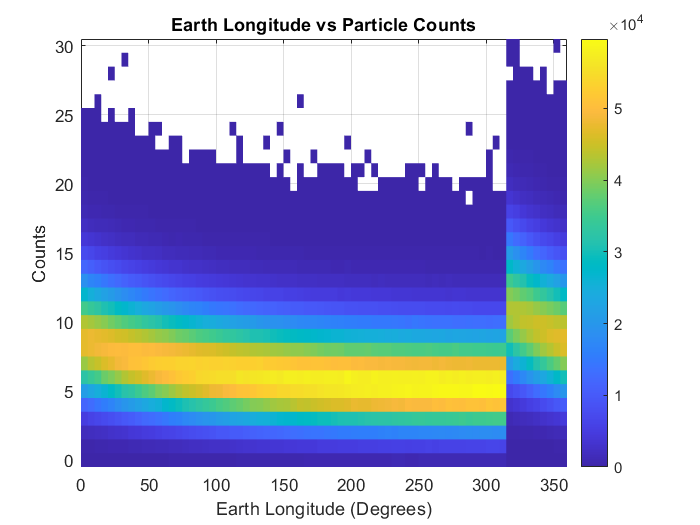

histogram2(mydata(1:end,3),mydata(1:end,4),'DisplayStyle','tile')
colorbar
title('Earth Longitude vs Particle Counts')
xlabel('Earth Longitude (Degrees)')
ylabel('Counts')

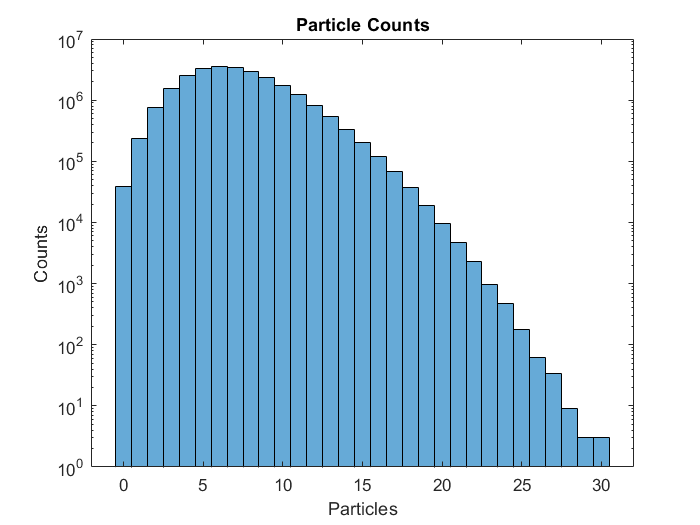

histogram(mydata(1:end,4))
set(gca,'Yscale','log')
title('Particle Counts')
xlabel('Particles')
ylabel('Counts')

The graphs above are Two-Dimensional histograms which plot two data sets against one another so we can compare them. Initially we can see that the Time vs Particle Counts graph looks generally uniform throughout. The Solar Phase also looks uniform throughout, but in the Earth Longitude graph we can see that there is a discontinuous jump in the graph at around 320 degrees and there is also some sort of decay in the peak of counts. It looks like the discountinous jump on the right side is where the plot begins and moves over to the left side of the graph. For the regular histogram of the particle counts we can see that the distribution looks like a Poisson distribution, the log normal looks like a Poisson distribution and because we know that we have discrete counts and not a continuous distribution. 

Looking deeper into the graphs, if we zoom in on the Time graph we can see that there are some fluxuations in the data that looks like two waves crossing each other 180 degrees out of phase. This seems like this could come from some sort of energy field with a certain frequency that causes distortion in the particle counts, could be the reciever on the satellite or frequencies of high energy particles. This and the trend that we seen in the Earth Phase data show us that the the distribution does not remain constant and in fact varies with time and depends on mostly the longitude of the satellite. This may be due to changes in the Earth's magnetic field causing charged particles to enter the telescope at higher or lower rates. The jump in the data seems to be an error of some sort or could be due to where we started collecting data. Either the X axis (the degrees) are off by 320 degrees or we started collecting data at that point which then drifts down to a steady level. Regardless of the reason it is clear that we do not have a consistent PDF but instead have a PDF that varies in time which we need to account for if we want to take accurate measurements.

To make a PDF that varies in time with our data set we can take mulitple "slices" accross the Earth longitude vs particle count data and find the mean and standard deviation at those points. We can then fit a curve to these points and come up with a PDF that has parameters that depend on Earth's longitude.

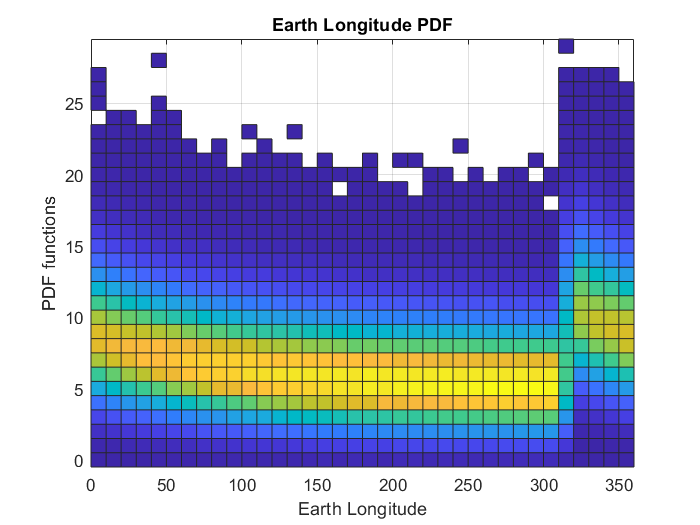

sliceint = 10;
movingmean = zeros(1,25920);
movingmean(1) = mean(mydata(1:sliceint,4));
for k = 1:((25920001 - 2)/sliceint)
    movingmean(k+1) = mean(mydata(sliceint*k:sliceint*k+sliceint,4));
end 
movingpdf = poissrnd(movingmean.',[2592000 1]);

histogram2(mydata(1:sliceint:(end-1),3),movingpdf,'DisplayStyle','tile')
title('Earth Longitude PDF')
xlabel('Earth Longitude')
ylabel('PDF functions')

From taking "slices" and forming PDFs from the mean we can recreate a PDF that has dependence on Earth's Longitude. From the graph we can see that our PDF approximation follows the same patern that the orignial graph follows. The discontinuos part is still there but we can shift that around if we move the right side to the left. The graph's precision can be increased by taking smaller slices, but the code can take a long time ot run. 

To find out the probability that we have a 100 ms GRB at different times we will have to use different slices from our PDF to find these. I will find the probability needed from early on before the decay, the middle section where it flatens out, and after the discountious section.

prob5sigma = 1/3.5e6;
numseconds = 100; %ms
det1 = poissinv(1-prob5sigma/numseconds, movingmean(200))

det1 = 28

probability1 = (1 - poisscdf(det1,movingmean(200)))*numseconds

probability1 = 7.6339e-08


det2 = poissinv(1-prob5sigma/numseconds, movingmean(20000))

det2 = 23

probability2 = (1 - poisscdf(det2,movingmean(20000)))*numseconds

probability2 = 2.2282e-07


det3 = poissinv(1-prob5sigma/numseconds, movingmean(210000))

det3 = 31

probability3 = (1 - poisscdf(det3,movingmean(2100000)))*numseconds

probability3 = 9.2457e-10

As we can see the probability that we find a GRB is significantly lower in the first section and the last section but higher in the flat section of the PDF.

Problem 2

h5disp('images.h5');

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


image1 = h5read('images.h5','/image1');
imagestack = h5read('images.h5','/imagestack');

## Problem 2: Telescope Images

Telescopes that take images also have backgroun noise to images. In an image a faint pixel could be due to the random background or it could actually be a very faint galaxy that is harder to see. The background goes not come from stars that are in the image but rather from radiation that comes from everywhere in space. In this example we have 10 images that each have their own background spectrum and stars that we can see are bright spots. We want to examine the data as much as we can to see if there is any signal contamination and to extract the background PDF.   

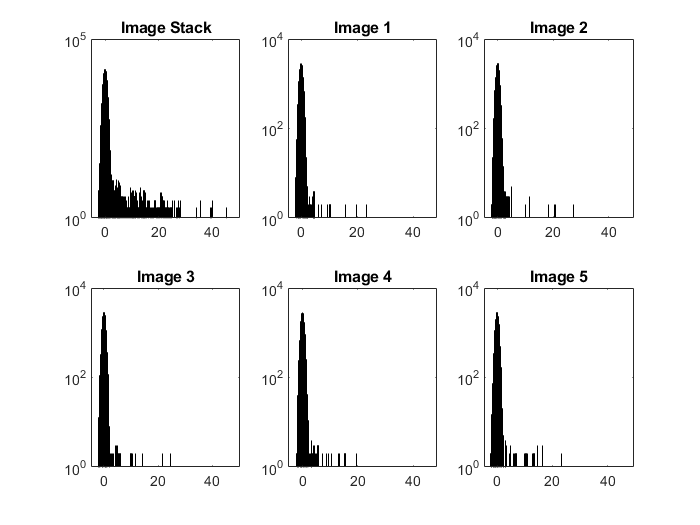

subplot(2,3,1)
histogram(imagestack)
set(gca,'Yscale','Log')
title('Image Stack')

subplot(2,3,2)
histogram(imagestack(1,:,:))
set(gca,'Yscale','Log')
title('Image 1')

subplot(2,3,3)
histogram(imagestack(2,:,:))
set(gca,'Yscale','Log')
title('Image 2')

subplot(2,3,4)
histogram(imagestack(3,:,:))
set(gca,'Yscale','Log')
title('Image 3')

subplot(2,3,5)
histogram(imagestack(4,:,:))
set(gca,'Yscale','Log')
title('Image 4')

subplot(2,3,6)
histogram(imagestack(5,:,:))
set(gca,'Yscale','Log')
title('Image 5')

From looking at the graphs of the intensity from all different images we can see that there is some noise spiking outside of the background distribution. These are stars within the image. From the fact that the stars do not move realtive to the image we can subtract the images from each other to obtain a star free background image.

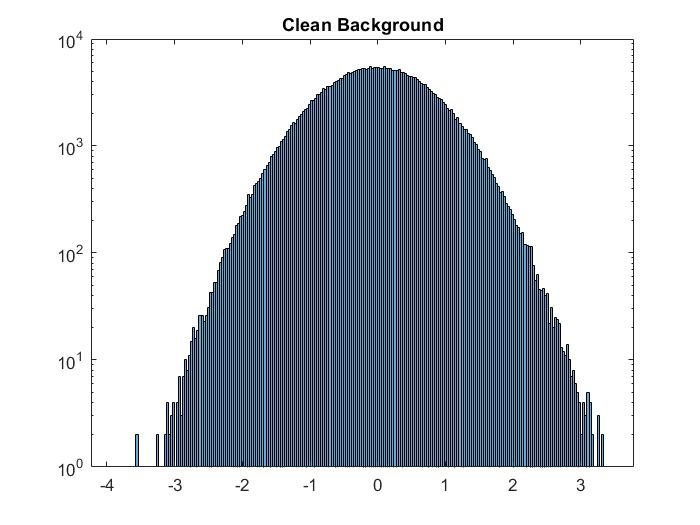

subplot(1,1,1)
cleanimage = imagestack(1,:,:) - imagestack(2:10,:,:);
histogram(cleanimage)
set(gca,'Yscale','Log')
title('Clean Background')

From the graph of the cleaned up image we can see that we still have some anamolies inside our data set even after removing all the stars. There is a very large spike close to the mean, as well as some noise closer to the edges of the distribution. From this we can still create a PDF. Based on the desciption of the pictures and the shape of the graph we can assume that we have a zero mean Gaussian. 

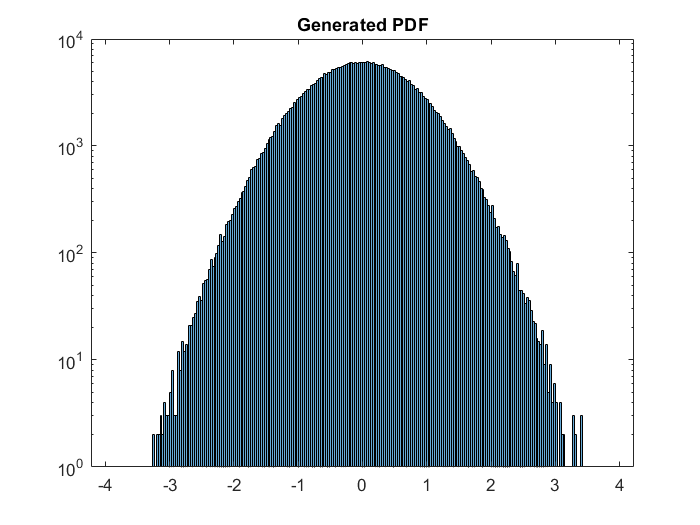

standard = std(cleanimage,0,'all');
PDF = normrnd(0,standard,[10 200 200]);
histogram(PDF)
set(gca,'Yscale','Log')
title('Generated PDF')

To find a very faint star we need to find the probability that the background will produce a very small signal or smaller than what we would consider faint. We can compare the data of each image with the background distribution to find out if there is a very faint star within our data. A very faint star is going to be left of the mean in each image. We can find the intensity of our faint star by finding the minimum value associated with each image without the background included.

min1 = min(imagestack(1,:,:),[],'all');
min2 = min(imagestack(2,:,:),[],'all');
min3 = min(imagestack(3,:,:),[],'all');
min4 = min(imagestack(4,:,:),[],'all');
min5 = min(imagestack(5,:,:),[],'all');
min6 = min(imagestack(6,:,:),[],'all');
min7 = min(imagestack(7,:,:),[],'all');
min8 = min(imagestack(8,:,:),[],'all');
min9 = min(imagestack(9,:,:),[],'all');
min10 = min(imagestack(10,:,:),[],'all');
aveloc = (min1+min2+min3+min4+min5+min6+min7+min8+min9+min10)/10

aveloc = -2.4240

Based on the data it appears that we have a star at -2.4240.

If we were looking for a bright star instead of a faint star we would need to produce a different PDF function even though we are using the same data because the region we are looking in has a different level of noise and hence a different probability of a random even occuring. 